## Q5b) Melbourne Street Modelling

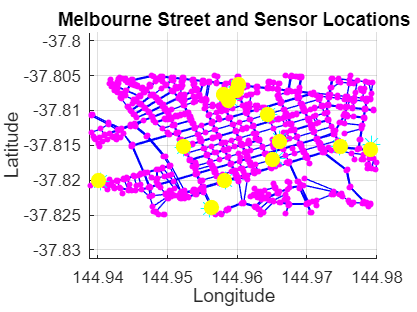

clear
close all
% load data
load_MPC_data % external script for clarity
Load_Melbourne_StData

% plot sensor locations
plot_q5_b

Building a regression model by adding more modelling information

- Topological Features: Centrality

- Space Suntax: Integration Index

% find centrality metric
% make a graph from edge and node data
G = graph(Melbourne_Edgelist.idx1, Melbourne_Edgelist.idx2);
G.Nodes = Melbourne_Node;

% getting centrality metrics
degreeCentrality = centrality(G, 'degree');
closenessCentrality = centrality(G, 'closeness');
betweennessCentrality = centrality(G, 'betweenness');
eigenvectorCentrality = centrality(G, 'eigenvector');
pageRankCentrality = centrality(G, 'pagerank');

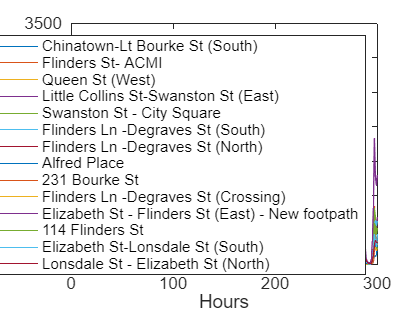

% ok lets look at the data
figure;
plot(sen_data.count)
xlabel("Hours")
ylabel("Pedestrian Count")
legend(sen_data.name)

% get IDW predictions for all nodes
time_sim = 300;
predi = zeros(time_sim,height(G.Nodes));
tic
for i = 1:height(G.Nodes)
    for j = 1:time_sim
        % need to get distance between target node and sensor nodes
        predi(j,i) = IDWprediction(G, i, sen_data.count(j, :), sen_data.Node_idx);
    end
end
toc

Elapsed time is 115.504066 seconds.


% assume a 24 hr period
model_fit = @(b, x) b(2).*x(:,2).*(... % scaling term (betweenness)
    b(1).*sin((2*pi/24).*x(:,1) + (13*pi/12))) ... % daily fluxuation term
    + b(3).*sin((2*pi/5).*x(:,1) + b(5))... % daily traffic pattern term
    + b(2).*x(:,2) ... % offset term
    + b(4).*x(:,3); % offset term
beta0 = [1 1 1 1 1]; % An arbitrary guess

% split training data
n = length(sen_data.count(:,1));
train_p = 0.8

train_p = 0.8000

train_size = round(train_p * n);

% make variables matrix
% X = [[1:300]',...
%     betweennessCentrality(sen_data.Node_idx(1)).*ones(300,1), ...
%     predi(:,2)... % adjacent node
%     ];
X = [[1:train_size]',...
    betweennessCentrality(sen_data.Node_idx(1)).*ones(train_size,1), ...
    predi(1:train_size,2)... % adjacent node
    ];

mdl = fitnlm(X,sen_data.count(1:train_size,1),model_fit,beta0)

mdl = Nonlinear regression model:
    y ~ b2*x2*(b1*sin((2*pi/24)*x1 + (13*pi/12))) + b3*sin((2*pi/5)*x1 + b5) + b2*x2 + b4*x3

Estimated Coefficients:
          Estimate       SE        tStat        pValue  
          ________    ________    ________    __________

    b1     0.91162     0.28278      3.2238     0.0014447
    b2    0.038259    0.020647       1.853       0.06514
    b3     -14.245       17.89    -0.79622       0.42671
    b4     0.76258     0.10876      7.0116    2.4827e-11
    b5      -4.742      1.2562     -3.7748    0.00020287


Number of observations: 240, Error degrees of freedom: 235
Root Mean Squared Error: 196
R-Squared: 0.634,  Adjusted R-Squared 0.628
F-statistic vs. zero model: 234, p-value = 4.3e-89

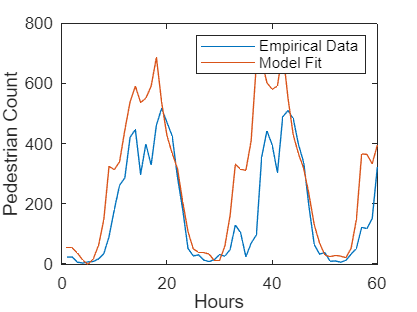


X_new = [[train_size+1:n]',...
    betweennessCentrality(sen_data.Node_idx(1)).*ones(n-train_size,1), ...
    predi(train_size+1:n,2)... % adjacent node
    ];
pred_data = predict(mdl,X_new);

figure;
plot(sen_data.count(train_size+1:end,1))
hold on
plot(pred_data)
legend(["Empirical Data","Model Fit"])
xlabel("Hours")
ylabel("Pedestrian Count")

sen_data.mdl = {}

sen_data = struct with fields:
       count: [300×14 double]
         Lat: [14×1 double]
         Lon: [14×1 double]
     Raw_idx: [11 25 53 56 62 64 65 17 108 109 114 123 60 61]
    Node_idx: [613 554 582 61 89 562 505 597 1025 763 505 950 395 701]
        name: ["Chinatown-Lt Bourke St (South)"    "Flinders St- ACMI"    "Queen St (West)"    "Little Collins St-Swanston St (East)"    "Swanston St - City Square"    "Flinders Ln -Degraves St (South)"    …    ] (1×14 string)
         mdl: {}



for i = 1:length(sen_data.Lat)
    mdl = dd_reg_model(sen_data.Node_idx(i), sen_data, G, betweennessCentrality(sen_data.Node_idx(i)), predi, train_size);
    sen_data.mdl{i} = mdl;
end